 Tests

Distributions = load("Regulations\Distributions.mat");

rearDILTest =  DistributionTest(0.3,  50,  500, -45, 80, 15, -5, Distributions.A3.I);
frontDILTest = DistributionTest(0.3, 175, 1000, -45, 80, 15, -5, Distributions.A3.I);
sideDILTest =  DistributionTest(0  , 0.6,  280,   5, 65, 15, -5, Distributions.A3.IV);
rearSLTest =   DistributionTest(0.3,  60,  260, -45, 45, 15, -5, Distributions.A3.I);
centralSLTest= DistributionTest(0.3,  25,  110, -10, 10, 10, -5, Distributions.A3.III);

Resources

Define LEDS

amberLed = Led('Lumen III/C503B-ACN-CY0Z0252.xml')

amberLed =   LED "C503B-ACN-CY0Z0252": 5.860cd - 12.000cd, 584nm - 596nm

redLed = Led('Lumen III/C503B-RCN-CX0Y0AA1.xml')

redLed =   LED "C503B-RCN-CX0Y0AA1": 4.180cd - 8.200cd, 618nm - 630nm

Define Covers

% Source: https://www.professionalplastics.com/professionalplastics/content/downloads/PolycarbonateGP_DataSheet2015.pdf
% n = 1.586, transmittance 0.118" = 86%
polycarbonateFilm = FlatCover(1.586, 50.3212630904, 0.0008);
trailingAngle = 90 - atand(11.14/74.33)

trailingAngle = 81.4764

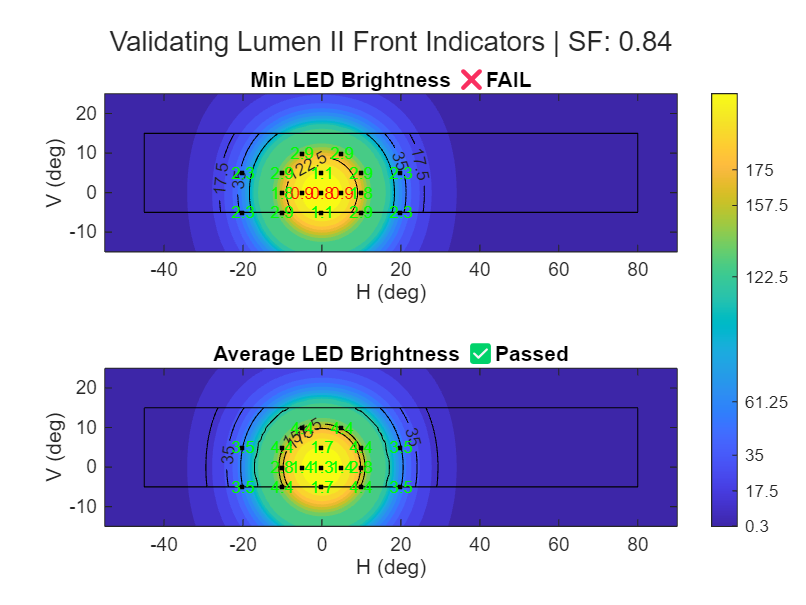

frontIndicators = Lamp("Lumen II Front Indicators");
frontIndicators.Add(LedArray(amberLed, 30, 0, 0));
frontIndicators.Add(polycarbonateFilm.Angle(0,0));
frontDILTest.Validate(frontIndicators);

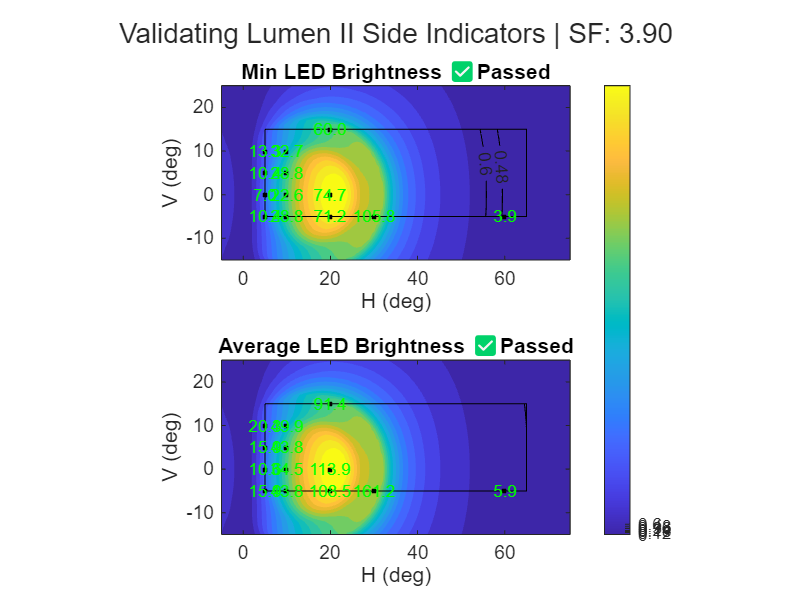

sideIndicators = Lamp("Lumen II Side Indicators");
sideIndicators.Add(LedArray(amberLed, 5, 15, 0));
sideIndicators.Add(polycarbonateFilm.Angle(90,0));
sideDILTest.Validate(sideIndicators);

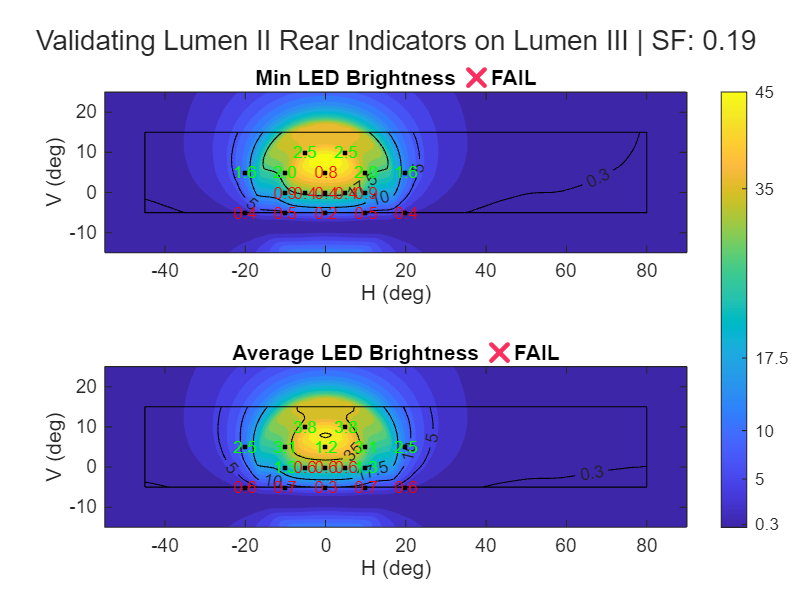

rearIndicators = Lamp("Lumen II Rear Indicators on Lumen III");
rearIndicators.Add(LedArray(amberLed, 10, 0, 0));
rearIndicators.Add(polycarbonateFilm.Angle(0, trailingAngle));
rearDILTest.Validate(rearIndicators);

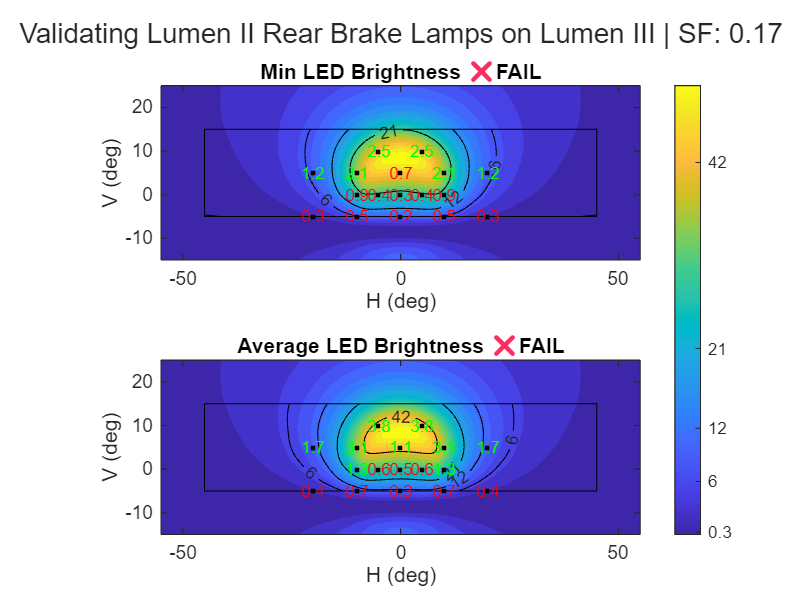

rearBrakeLamps = Lamp("Lumen II Rear Brake Lamps on Lumen III");
rearBrakeLamps.Add(LedArray(redLed, 15, 0, 0));
rearBrakeLamps.Add(polycarbonateFilm.Angle(0, trailingAngle));
rearSLTest.Validate(rearBrakeLamps);

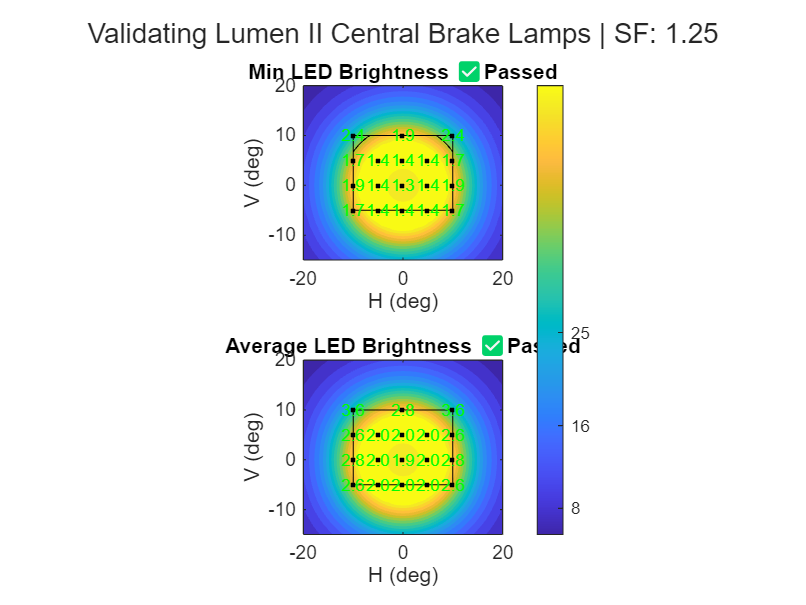

centralBrakeLamps = Lamp("Lumen II Central Brake Lamps");
centralBrakeLamps.Add(LedArray(redLed, 10, 0, 0));
centralBrakeLamps.Add(polycarbonateFilm.Angle(0,0));
centralSLTest.Validate(centralBrakeLamps);